# Serie de Fourier

[⇦ Información general del análisis de Fourier](matlab: OpenOverview)

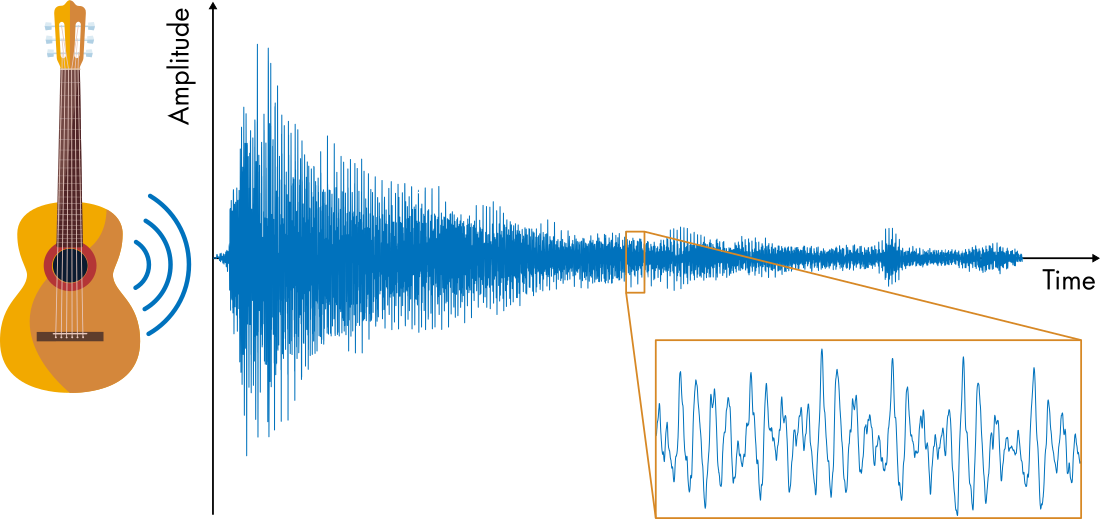

Cuando se toca una guitarra, la vibración de las cuerdas y el cuerpo de la guitarra emiten una onda de presión. La amplitud de una nota de guitarra grabada se traza aquí en el dominio del tiempo. Si quisieras determinar la frecuencia fundamental de la señal para usar en un afinador de guitarra, ¿cómo lo harías? Un examen superficial de la señal en el dominio del tiempo revela poco. Al hacer zoom en la señal se observan una serie de patrones repetitivos. Incluso desde esta vista, es difícil determinar qué frecuencias están presentes. Hay una manera más fácil de analizar esta señal: trazarla en el dominio de la frecuencia.

**Objetivos de aprendizaje**

- Comparar señales en los dominios del tiempo y de la frecuencia.

- Analizar señales de audio en el dominio de la frecuencia.

- Visualizar modos de serie de Fourier.

- Describir cómo se representa el desplazamiento de fase en una serie de Fourier.

- Discutir la magnitud y la fase.

## El dominio de la frecuencia

El análisis de Fourier se trata de tomar señales del dominio del tiempo (o del espacio) y analizarlas en *el dominio de la frecuencia*.

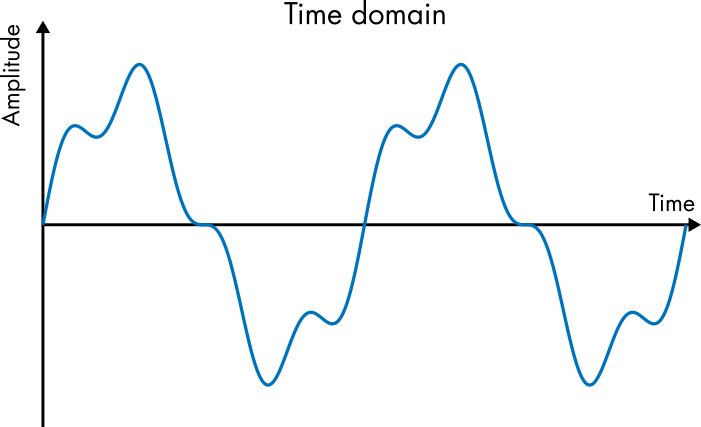      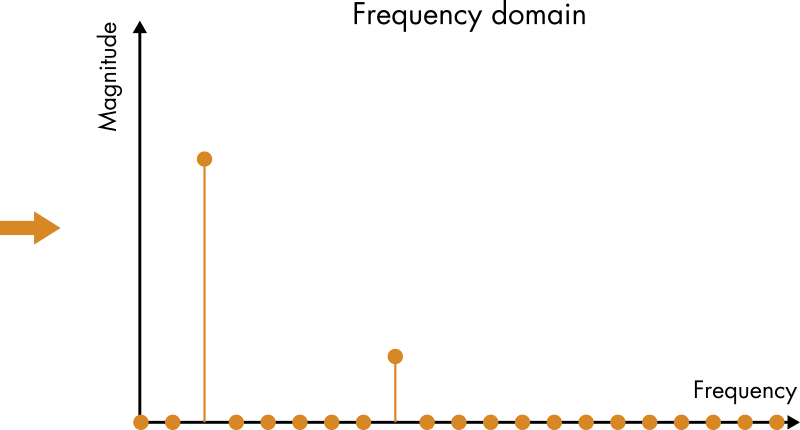

*Una señal en los dominios del tiempo y de la frecuencia. Mientras que la señal tiene mucho movimiento en el dominio del tiempo, en realidad es una simple suma de dos funciones seno, como se ilustra en el dominio de la frecuencia.*

Cada frecuencia presente en una señal crea un pico en el dominio de la frecuencia. Cuanto más fuerte sea esa frecuencia en la señal, mayor será el pico en el dominio de la frecuencia.

## Una sola función seno

Considere la función 


$$y(t) = A \sin( 2\pi f t)$$


Esta función seno tiene una frecuencia de $f$ Hz. Suponga que $f=220$ Hz. Cuando se representa en el dominio del tiempo, la función se traza en función del tiempo, produciendo la curva seno habitual. En el dominio de la frecuencia, la función se representa por un solo pico en 220 Hz. La amplitud $A$ determina la altura del pico en el dominio de la frecuencia. Las gráficas a continuación ilustran $y$ en ambos dominios del tiempo y de la frecuencia.

**Tarea.** Ejecute esta sección para generar las gráficas. Haga clic en la barra azul a la izquierda 

o haga clic   **Run Section** en la sección **Section** de la pestaña **Live Editor**.

**Tarea.** Intente ajustar los controles deslizantes para cambiar la curva.

- ¿Qué sucede en cada gráfico cuando se aumenta $f$, la frecuencia de la señal seno?

- ¿Cómo cambian los gráficos cuando se aumenta la amplitud $A$?

f = 220;
A = 1.5;
plotSingleSine(A,f); % Función auxiliar que genera las gráficas

    **Actividad.** Una señal de 220 Hz es única; representa una nota A "perfecta". Puedes escuchar la señal de 220 Hz (1) generando la curva seno y (2) reproduciéndola como una señal de audio.

**Tarea 1.** Se ha creado la variable de tiempo t para ti. Usando `t`, crea la señal `y`, una onda seno con una frecuencia de 220 Hz y una amplitud $A=1$.

Fs = 44.1e3; % Tasa de muestreo de audio
t = 0:1/Fs:1; % Variable de tiempo de 1 segundo
% Calcule su señal y aquí


**Tarea 2.** Llama a la función [`soundsc`](https://www.mathworks.com/help/matlab/ref/soundsc.html) para reproducir la señal de audio utilizando la sintaxis

donde y es la señal y `Fs` es la tasa de muestreo. Luego, ejecute la sección para reproducir `y` como señal de audio.

% Reproducir la señal de audio aquí



**Tarea 3.** Si se divide o multiplica la frecuencia por 2, se obtiene la misma nota, pero una octava más alta o más baja. Prueba ajustar la frecuencia a 110 Hz para escuchar la nota A una octava más baja.

## Una señal real

La simple nota de 220 Hz probablemente no sonó muy agradable. Los sonidos generados por instrumentos musicales tienden a tener varias frecuencias complementarias (conocidas como armónicos) que crean un sonido más rico. Escucha la nota de guitarra que se reproduce a continuación.

[yGuitar,FsGuitar] = audioread("Anote.mp3");
soundsc(yGuitar,FsGuitar)


Puede analizar la nota de guitarra en el dominio del tiempo trazando la señal de audio. A continuación, se traza aproximadamente 10 milisegundos de la señal.

tGuitar = (1:length(yGuitar))/FsGuitar; % Variable de tiempo
% Genere la gráfica
figure 
plot(tGuitar,yGuitar(:,1),"Linewidth",1)
xlim([0.1145 0.1245])
xlabel("t (s)")
ylabel("Amplitud")

** Reflexionar.**

- Compare esta señal con la señal seno simple trazada en la actividad anterior. ¿Cómo esperas que difiera el dominio de la frecuencia de esta señal del único pico que observaste para la señal seno simple?

Hay más que la frecuencia fundamental en la nota A de la guitarra. Es difícil saber exactamente cuántos armónicos hay presentes, pero un buen lugar para empezar es considerar una función con tres frecuencias:


$$y(t) = b_1 \sin( 2\pi f_1 t) + b_2 \sin( 2\pi f_2 t) + b_3 \sin( 2\pi f_3 t) $$


donde $b_i$ es la amplitud del componente $i$ y $f_i$ es su frecuencia en Hz. Siga los pasos a continuación para diseñar $y$ para que suene como la grabación (bueno, tanto como sea posible). La frecuencia fundamental de la nota A de guitarra es de 110 Hz, el primer armónico es de 220 Hz y el segundo armónico es de 330 Hz. Utilice estos valores para las frecuencias $f_i$. Inicialmente, asuma que cada $b_i=1$. Use la variable predefinida `t` para ayudarle a crear su señal.

Tarea 1. Definir la señal `y` en MATLAB.

Fs = 44.1e3; % Tasa de muestreo de audio
t = 0:1/Fs:1; % Variable de tiempo de 1 segundo
% Definir los coeficientes b1, b2 y b3


% Definir las frecuencias f1, f2 y f3 en Hz


% Crear la señal y



**Tarea 2.** Graficar la señal y en función de `t` utilizando la función [`plot`](https://www.mathworks.com/help/matlab/ref/plot.html). Ajustar los límites del $x$-eje a `[0,0.01]` utilizando la función [`xlim`](https://www.mathworks.com/help/matlab/ref/xlim.html).

Tarea 3. Utilice la función [`soundsc`](https://www.mathworks.com/help/matlab/ref/soundsc.html) para reproducir su señal.

**Tarea 4.** Ajuste los coeficientes bi para que la señal reproduzca mejor la señal de guitarra tanto en la gráfica como en el sonido. En esta señal, el componente de 220 Hz es dominante. Tenga en cuenta que la señal generada nunca coincidirá perfectamente, por lo que solo debe hacer 3 o 4 ajustes.

 **Reflexionar.** 

- ¿Qué es lo que falta en $y(t)$ para reproducir la señal de guitarra?

## Serie de senos y cosenos de Fourier

Para reproducir de manera precisa una señal real periódica del mundo, a menudo se requieren más de tres frecuencias. A medida que se utilizan más frecuencias, escribir la función con muchas funciones senoidales se vuelve cada vez más difícil. En su lugar, se puede utilizar *la notación de sumatoria*. Por ejemplo, se podría reescribir la función anterior $y(t)$ como


$$y(t) = \sum_{i=1}^3 b_i \sin( 2\pi f_i t) $$


Las series de Fourier reproducen señales periódicas utilizando frecuencias infinitas (en teoría). En el procesamiento de señales práctico, solo se utilizan un número finito de frecuencias. *La serie de senos de Fourier* es una suma infinita de funciones seno:


$$f(t) = \sum_{n=1}^\infty b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


$L$ es un parámetro que determina la periodicidad de la función $f$, que tiene un período $2L$. Esto implica que $f$ siempre tendrá copias periódicas cada $2L$. Cada término en la suma se conoce como un* modo de Fourier*. Por ejemplo, el modo fundamental (con $n=1$) es

 
$$f_1 = \sin \left( \frac{\pi}{L} t \right)$$
 

El primer coeficiente $b_1$ determina cuán fuertemente se representa este modo en la suma total.

    **Actividad.** En esta actividad, creará varias funciones usando la aplicación Serie de Senos y Cosenos de Fourier. Haga clic en el enlace para abrir la aplicación, luego complete las tareas que se enumeran a continuación.

[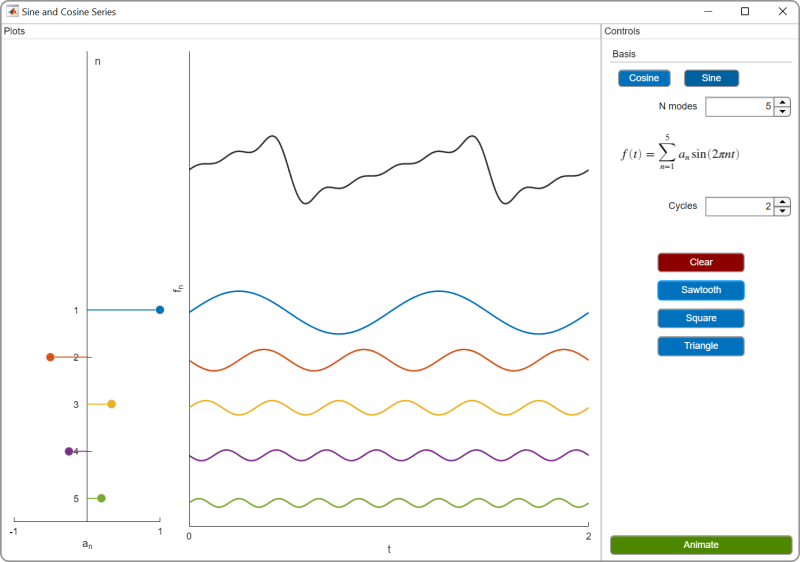](matlab: SinCosSeries)

[SinCosSeries.mlapp](matlab: SinCosSeries)

**Tarea 1.** Establecer la base de Fourier en seno.

**Tarea 2.** Crear la señal mostrada. Para hacerlo, haga clic y arrastre los coeficientes de Fourier para que $a_1 = 1$ y $a_3 = 3$. Estos se encuentran en el gráfico de tallo de la izquierda.

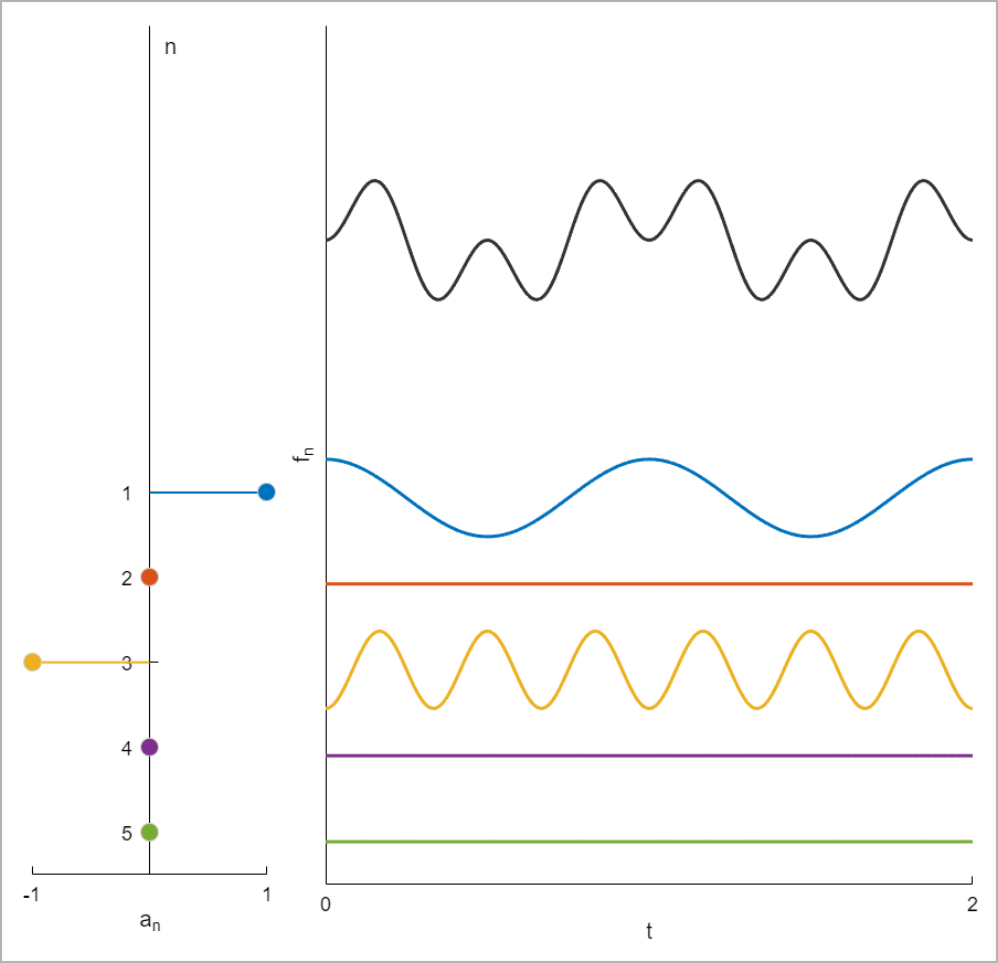

**Tarea 3.** Haga clic en el botón "animar" para ilustrar cómo se agregan los componentes para construir la función global.

**Tarea 4.** Ajuste los coeficientes de Fourier a (aproximadamente) $a_1=1$, $a_2=0.5$, $a_3=0.25$, $a_4=0.125$, $a_5=0.0625$ y anime la gráfica. ¿Qué forma de onda se produce?

**Tarea 5.** Vuelva a crear las formas de onda que se muestran a continuación ajustando los coeficientes de Fourier (utilice una **base seno**).

(a) 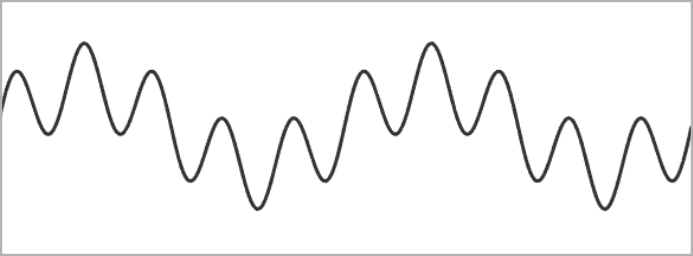

(b) 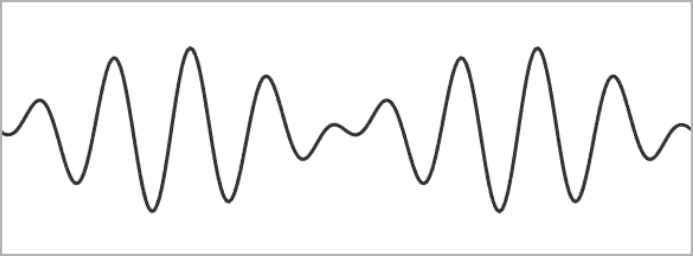

**Pista:** use dos frecuencias vecinas para recrear la señal (b).

## Serie de Fourier

La serie de senos de Fourier contiene infinitas frecuencias. Esto permite que la serie produzca muchas formas de onda diferentes. Sin embargo, todas las frecuencias producidas usando solo modos senoidales tendrán *fase cero*.

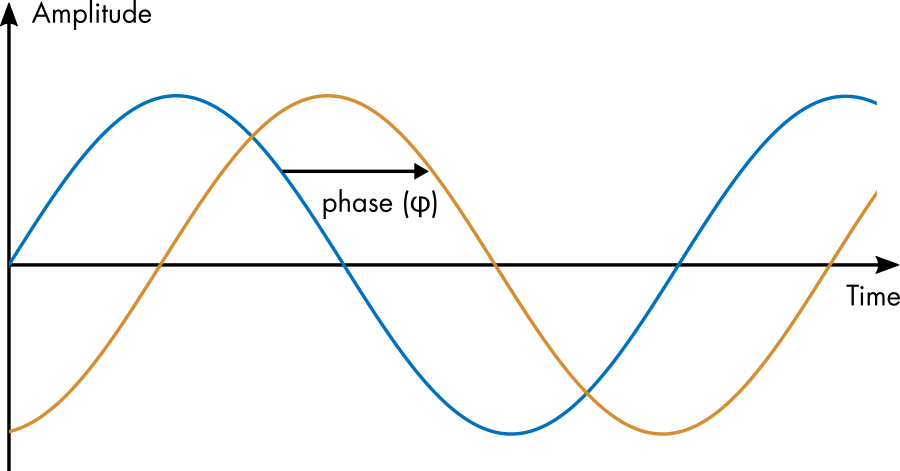

*La fase o desplazamiento de fase de una señal es cuánto ha sido desplazada horizontalmente. *

Las señales reales típicamente no tienen fase cero, por lo que la serie de senos de Fourier es insuficiente para representarlas. Sin embargo, agregar una serie de cosenos permite producir señales con cualquier fase.

### Definición

Una definición estándar para la serie de Fourier es la suma de las series de coseno y seno:


$$f(t) = \frac{a_0}{2}  + \sum_{n=1}^\infty a_n \cos\left( \frac{ n \pi } {L}  t \right) + b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


Con esta adición, ahora hay dos conjuntos de coeficientes: los coeficientes de serie de coseno $a_n$ y los coeficientes de seno $b_n$. Los términos de seno tienen una fase de  $0^{\circ}$, mientras que las señales de coseno tienen una fase de $90^{\circ}$ (asumiendo que la fase cero corresponde a una señal seno). Si combina una señal de coseno y seno con la misma frecuencia, produce una señal desfasada:


$$a \cos (\omega t) + b \sin( \omega t) = c \sin( \omega t  -  \phi)$$


donde la relación de los coeficientes $a$ y $b$ determina el desfase, $\phi$.

    **Actividad.** Cree señales con desfase utilizando series de Fourier completando las siguientes tareas.

Taera 1. Abra la aplicación Serie de Fourier Interactiva.

[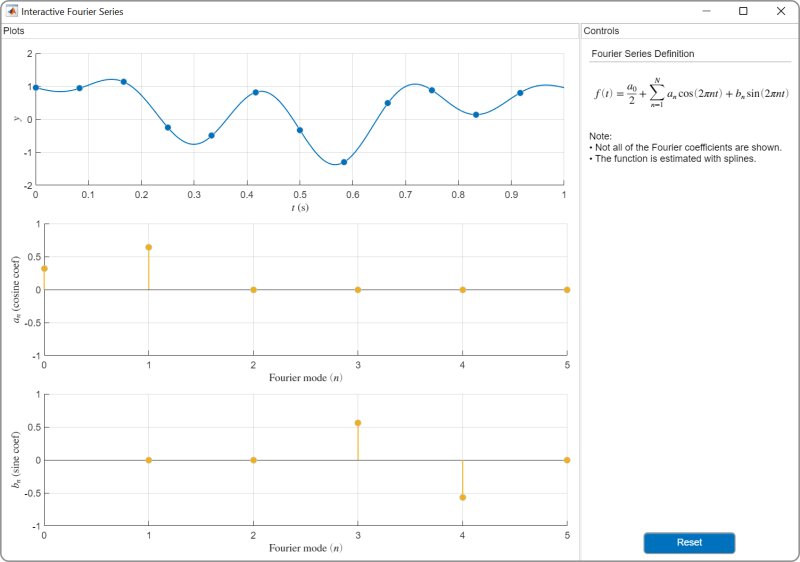](matlab: InteractiveFourierSeries)

[InteractiveFourierSeries.mlapp](matlab: InteractiveFourierSeries)

En la aplicación, $L=1/2$ de forma predeterminada, por lo que el período de la serie de Fourier es de 1 s. Esto implica que el modo fundamental con índice $n=1$ tiene una frecuencia de 1 Hz. Para ajustar los coeficientes de modo, haga clic y arrastre los círculos amarillos. Para este ejercicio, no arrastre los círculos azules.

**Tarea 2.** Ajuste los coeficientes de Fourier para crear una señal de 1 Hz con cero fase ($\phi = 0^{\circ}$) (en relación a una función seno).

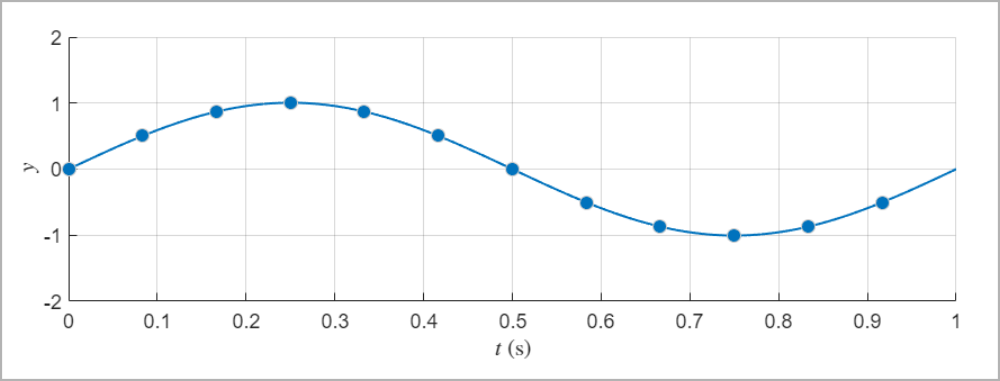

**Tarea 3.** Ajuste los coeficientes de Fourier para crear una señal de 2 Hz con un desfase de $\phi=90^{\circ}$ (en relación a una función seno).

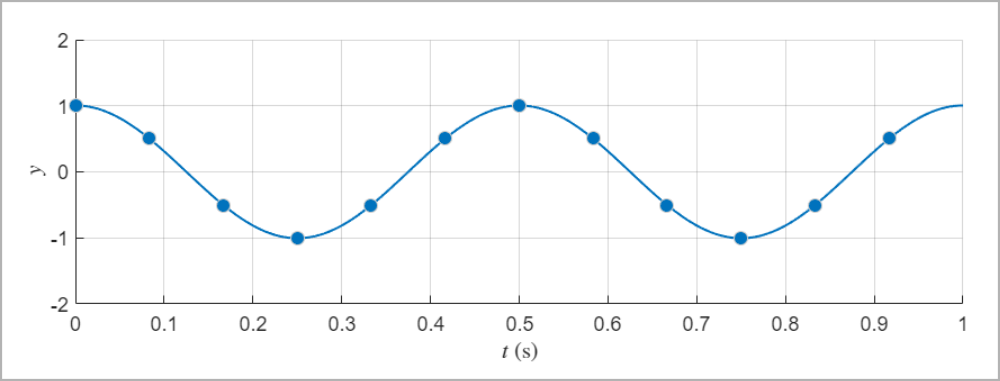

**Tarea 4.** Una señal de 1 Hz con un desfase de $\phi=45^{\circ}$ (en relación a una función seno).

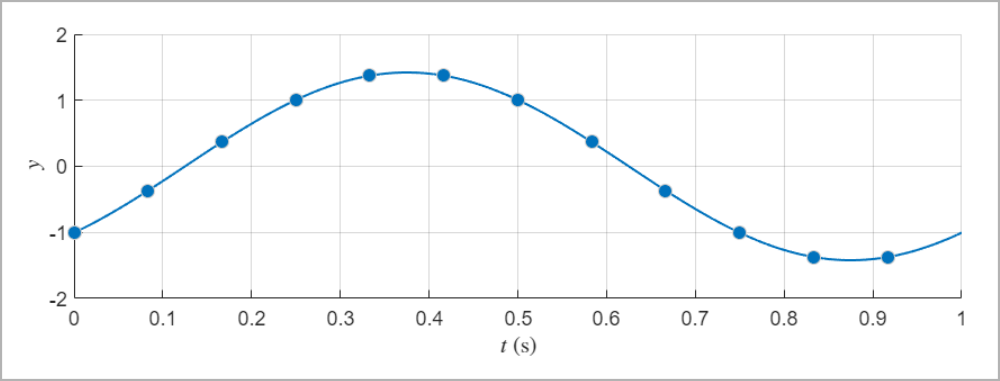

## Resolviendo para los coeficientes de la serie de Fourier.

La señal de audio de la nota A de la guitarra claramente tiene al menos tres frecuencias.

**Tarea. **Ejecute esta sección para mostrar la señal de la guitarra.

% Este código reproduce el sonido de la guitarra y traza parte de la señal
[yGuitar,FsGuitar] = audioread("Anote.mp3");
soundsc(yGuitar,FsGuitar)
plotGuitarSignal(yGuitar,FsGuitar,[0.3 0.33])
 

Pero, ¿cuáles son las frecuencias y cuán fuertemente está representada cada una? En otras palabras, ¿cómo se ve la señal de audio de la guitarra en el dominio de la frecuencia?

### Fórmulas de coeficiente de Fourier

En las actividades anteriores, ajustó los coeficientes de Fourier a mano. Afortunadamente, esto no es necesario para identificar los coeficientes de la serie de Fourier de una señal dada. Puede identificar los coeficientes utilizando dos fórmulas:


$$a_n = \frac{1}{L} \int_{-L}^{L} y(t) \cos \left( \frac{ n \pi }{L} t \right) dt$$



$$b_n = \frac{1}{L} \int_{-L}^{L} y(t) \sin\left( \frac{ n \pi }{L} t \right) dt$$


Estas integrales calculan el peso del modo $n^{\text{th}}$ requerido para igualar la señal dada, $y(t)$. Cada modo tiene una frecuencia única, por lo que estas integrales determinan cuán fuertemente se representa cada frecuencia en la señal original $y(t)$. Tenga en cuenta que la función $y(t)$ debe ser periódica con un período de $2L$ para poder ser representada por la serie de Fourier. Si no lo es, entonces la serie de Fourier derivada no coincidirá con $y(t)$ en todas partes, sino que creará una extensión periódica de la función original con periodo .

La gráfica a continuación muestra los modos de Fourier de la señal de la guitarra estimados utilizando las fórmulas integrales y la regla del trapecio.

**Tarea.** Ejecute la sección para ver la nota A de la guitarra en el dominio de la frecuencia.

% Funciones de ayuda que estiman y trazan los coeficientes de Fourier
[freq,a,b] = computeGuitarFourierCoef(yGuitar,FsGuitar);
plotGuitarCoef(freq,a,b)
 

Intente hacer clic en un pico para crear un punto de datos. Puede utilizar esto para identificar la frecuencia de un modo. 

 **Reflexionar.** 

- ¿Cuál frecuencia es dominante?

- ¿Las frecuencias dominantes son puramente seno o coseno? 

- Basado en los coeficientes observados, ¿se puede hacer alguna declaración general sobre la fase de cada modo?

## Magnitud y fase de la serie de Fourier

### Magnitud

En la gráfica del dominio de la frecuencia anterior, puede parecer que la señal de 330 Hz tiene una amplitud casi igual a la señal de 220 Hz. Sin embargo, este no es el caso, ya que la magnitud de una frecuencia es una combinación de ambos coeficientes. Específicamente, la magnitud del modo $n^{\text{th}}$ es


$$A_n = \sqrt{ {a_n}^2 + {b_n}^2 }$$


 **Ejercicio.**

**Tarea 1.** Asegúrese de que se haya ejecutado la sección anterior para producir las variables: freq, `a` y `b`. 

**Tarea 2.** Calcule la magnitud de los coeficientes ($A_n$) a partir de los vectores `a` y `b`. Guarde el resultado en `A`. 

  **Consejo profesional.** Realice operaciones elemento a elemento en vectores colocando un carácter de período delante. Por ejemplo, para calcular el cuadrado del vector de coeficientes `a`, use `a.^2`.

% Calcula A aquí
% A debe ser un vector que contenga las magnitudes


**Tarea 3.** Trace las magnitudes en A contra las frecuencias en freq utilizando un gráfico de [`stem`](https://www.mathworks.com/help/matlab/ref/stem.html). Establezca los límites de frecuencia en `[0,600]` utilizando la función [`xlim`](https://www.mathworks.com/help/matlab/ref/xlim.html).

 **Reflexionar.** 

- ¿Cuál frecuencia es dominante?

- La frecuencia fundamental de la nota A de la guitarra es 110 Hz. ¿Tiene sentido esta gráfica para la nota A de la guitarra?

### Gráficas de magnitud y fase

El dominio de la frecuencia se puede visualizar trazando los coeficientes $a_n$ y $b_n$ o trazando la magnitud $A_n$. Sin embargo, la magnitud por sí sola no cuenta toda la historia. Se puede obtener una imagen más completa añadiendo un gráfico de la fase.

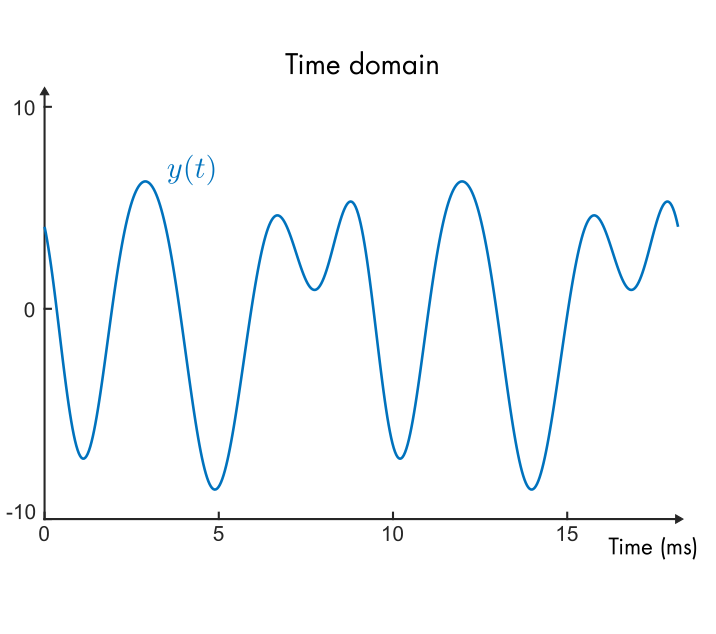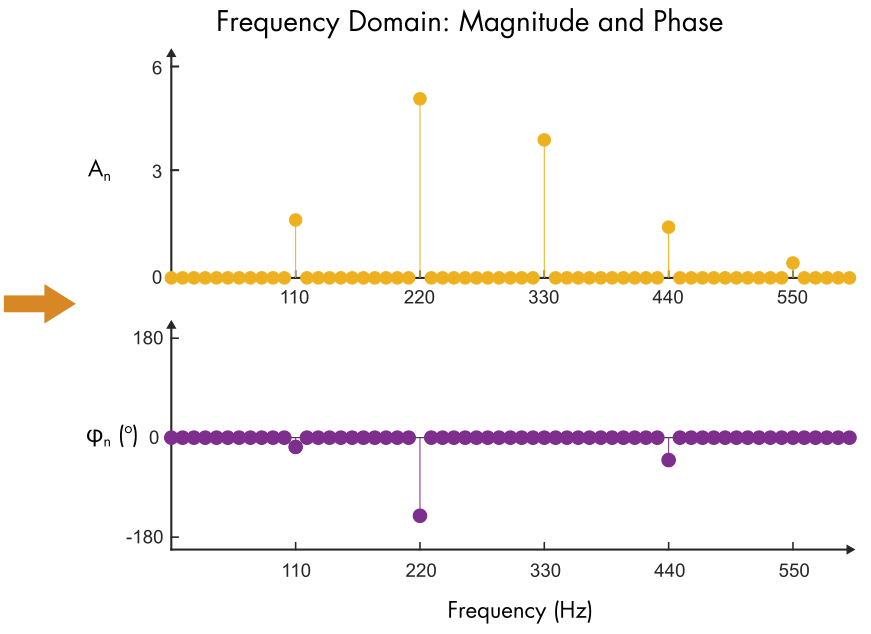

*Los 5 modos principales de la nota A de guitarra en el dominio del tiempo y del dominio de la frecuencia. *

*Aquí, el dominio de la frecuencia se grafica usando la magnitud y la fase.*

Esta gráfica suele ser más útil que la de $a_n$ y $b_n$ porque ilustra claramente dos características intuitivas de cada modo:

- **magnitud**: la fuerza del modo

- **fase**: cuánto se ha desplazado el modo a lo largo del eje temporal.

### Definición

La forma de magnitud-fase de la serie de Fourier tiene una definición formal como una suma de cosenos desfasados:


$$f(t) = \frac{A_0}{2} +  \sum_{n=1}^{\infty} A_n \cos\left( \frac{ n \pi } {L}  t - \phi_n \right)$$


Esta definición está relacionada con la definición de seno-coseno a través de

$A_n = \sqrt{a_n^2 + b_n^2}$     y     $\phi_n = \text{atan2}\left( b_n,a_n\right)$

Tenga en cuenta que el ángulo de fase se calcula utilizando la tangente inversa de dos argumentos. En MATLAB, esto se implementa en la función [`atan2`](https://www.mathworks.com/help/matlab/ref/atan2.html). 

  **Actividad.** En esta actividad, comparará las dos representaciones discutidas del dominio de la frecuencia: la representación de seno-coseno y la representación de magnitud-fase.

**Tarea 1.** Ejecute la aplicación Serie de Fourier: Magnitud y fase.

[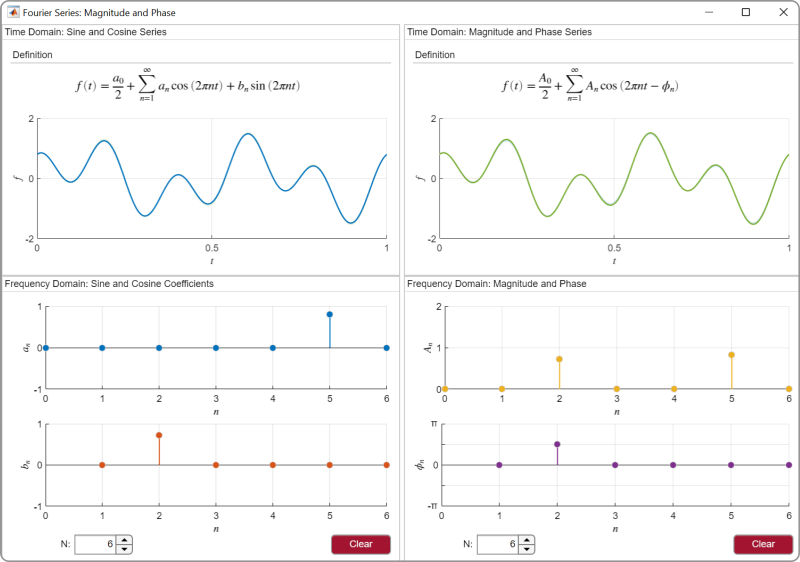](matlab: run MagnitudePhase.mlapp)

[`MagnitudePhase.mlapp`](matlab: run MagnitudePhase.mlapp)

Observe que el primer panel (a la izquierda) muestra la versión de seno-coseno del dominio de la frecuencia ($a_n$ y $b_n$). El panel derecho utiliza la magnitud ($A_n$) y la fase ($\phi_n$) en su lugar.

**Tarea 2.** Ajuste $a_1=-1$ y deje los demás $a_n, b_n=0$. Puede hacer clic y arrastrar el gráfico de tallo para ajustar los coeficientes. La primera gráfica de series temporales debería aparecer como se muestra a continuación.

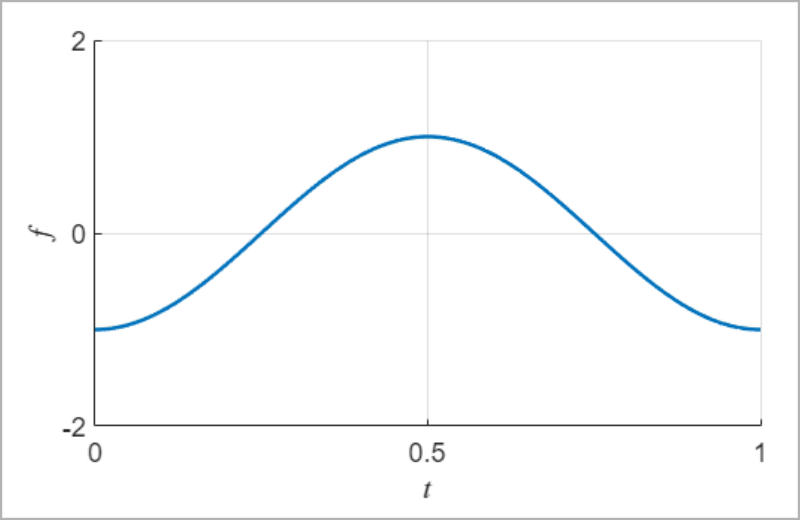

**Tarea 3.** Reproduzca la gráfica de la **Tarea 2** ajustando la magnitud ($A_n$) y la fase ($\phi_n$) en el segundo panel.

**Tarea 4.** Borre ambas gráficas. Luego, ajuste los coeficientes del dominio de la frecuencia $a_n$ y $b_n$ en el primer panel para crear la función:


$$f(t) = 0.5 - \sin(4 \pi t) + \cos( 4 \pi t)$$


Si es correcto, debería ver la serie temporal trazada a continuación.

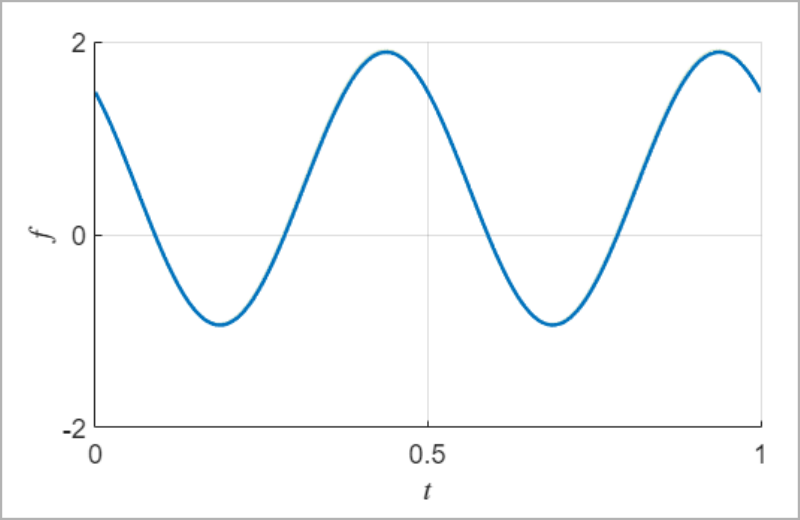

**Tarea 5.** Reproduzca la misma función de serie temporal $f(t)$ de la **Tarea 4** utilizando el segundo panel (a la derecha) ajustando los parámetros de magnitud $A_n$ y fase $\phi_n$. Si es correcto, la segunda gráfica de series temporales debería coincidir con la de la **Tarea 4**.

**Pista:** Solo necesita ajustar los parámetros de modo $n=0$ y $n=2$.

**Tarea 6.** Repita las **Tareas 4** y **5** para la función 


$$f(t) = \sin(2 \pi t) + \cos( 2 \pi t) + 0.5 \sin (12 \pi t)$$


[⇦ Descripción general del análisis de Fourier](matlab: OpenOverview)

**Funciones auxiliares**

function plotSingleSine(A,f)
    % Crea la gráfica de una función seno en 
    % el dominio del tiempo y de la frecuencia

    % Dominio del tiempo
    t = linspace(0,0.01,500);
    g = A*sin(2*pi*f*t);
    

    % Dominio de la frecuencia
    freq = 0:500;
    ghat = zeros(1,501);
    ghat(f+1) = A;
    
    figure("Position",[1 1 800 325])
    % Gráfica del dominio del tiempo
    subplot(1,2,1)
    plot(t,g,"linewidth",1)
    ylim([-3,3])
    title("Dominio del tiempo")
    xlabel("tiempo (s)")
    ylabel("Amplitud")
    
    % Gráfica del dominio de la frecuencia
    subplot(1,2,2)
    stem(freq,ghat,"filled")
    ylim([0,3])
    title("Dominio de la frecuencia")
    xlabel("frecuencia (Hz)")
    ylabel("Magnitud")
end

function plotGuitarSignal(yGuitar,FsGuitar,timeLimits)
    % Crea y etiqueta la gráfica de amplitud
    % para la señal de guitarra

    tGuitar = (1:length(yGuitar))/FsGuitar; % Variable de tiempo    
    % Generar la gráfica
    figure("Position",[1 1 900 325]) 
    plot(tGuitar,yGuitar(:,1),"Linewidth",1)
    xlim(timeLimits)
    xlabel("t (s)")
    ylabel("Amplitud")
    title("Dominio del tiempo")
end

function [freq,a,b] = computeGuitarFourierCoef(y,Fs)
    % Estima los coeficientes de la serie de Fourier
    % utilizando la regla del trapecio

    Nmodes = 1000;
    yc = y(1e4:2e4);
    
    tc = 1/Fs*(0:(length(yc)-1));
    L = tc(end)/2; % Se asume que el dominio es de 2L
    freq = (1:Nmodes)/(2*L); % Frecuencias

    % Estima los coeficientes utilizando la regla del trapecio
    a = zeros(1,Nmodes);
    b = zeros(1,Nmodes);
    a0 = 1/L*trapz(tc,yc);
    for n = 1:Nmodes
        a(n) = 1/L*trapz(tc,cos(n*pi/L*tc).*yc);
        b(n) = 1/L*trapz(tc,sin(n*pi/L*tc).*yc);
    end
end

function plotGuitarCoef(f,a,b)
    % Grafica los coeficientes de la guitarra
    % y agrega etiquetas

    % Grafica el resultado
    figure("Position",[1,1,900,325])
    stem(f,a,"Filled")
    hold on
    stem(f,b,"Filled")
    hold off
    xlabel("Frecuencia (Hz)")
    ylabel("Coeficiente")
    legend("a_n","b_n")
    title("Dominio de la frecuencia")
    xlim([0,600])
end